PSF = fspecial('gaussian', 13, 1);
I_src = im2double(imread('..\images\ceremony.jpg'));

## use imfilter

tic;
I_dst_1 = imfilter(I_src, PSF, 'same', 'conv');
t_1 = toc

t_1 = 0.0362

## use fourier transform

shift_PSF = zeros(size(PSF));
shift_PSF(floor(size(PSF,1)/2)+1, floor(size(PSF,2)/2)+1) = 1;
F_PSF = conj(fft2(shift_PSF, size(I_src, 1), size(I_src, 2))) .* ...
    fft2(PSF, size(I_src, 1), size(I_src, 2));
F_I_dst_2 = F_PSF .* fft2(I_src);
I_dst_2 = real(ifft2(F_I_dst_2));
t_2 = toc

t_2 = 0.1721

t_2 = t_2 - t_1;

## display images

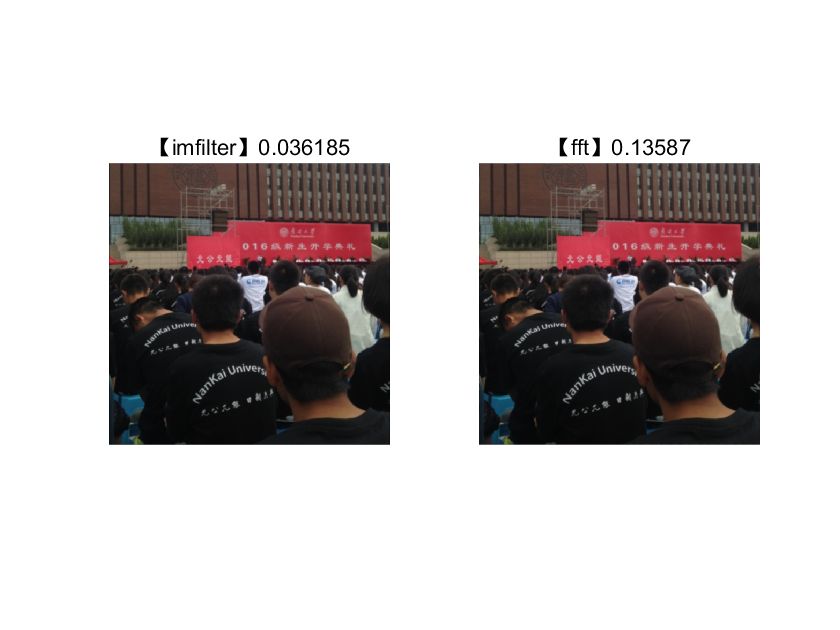

subplot(121);imshow(I_dst_1);title(['【imfilter】', num2str(t_1)]);
subplot(122);imshow(I_dst_2);title(['【fft】', num2str(t_2)]);